Watts-Strogatz demo: clustering and diameter vs shortcut probability q

Run this live script from the package folder so the helper functions are on the MATLAB path.

clearvars; close all; clc;

%DEMO_WS_Q_SWEEP Demo for Watts-Strogatz small-world networks.
%
% Shows how:
%   - average local clustering coefficient
%   - mean shortest path
%   - diameter
% change as rewiring probability q increases.

rng(2);


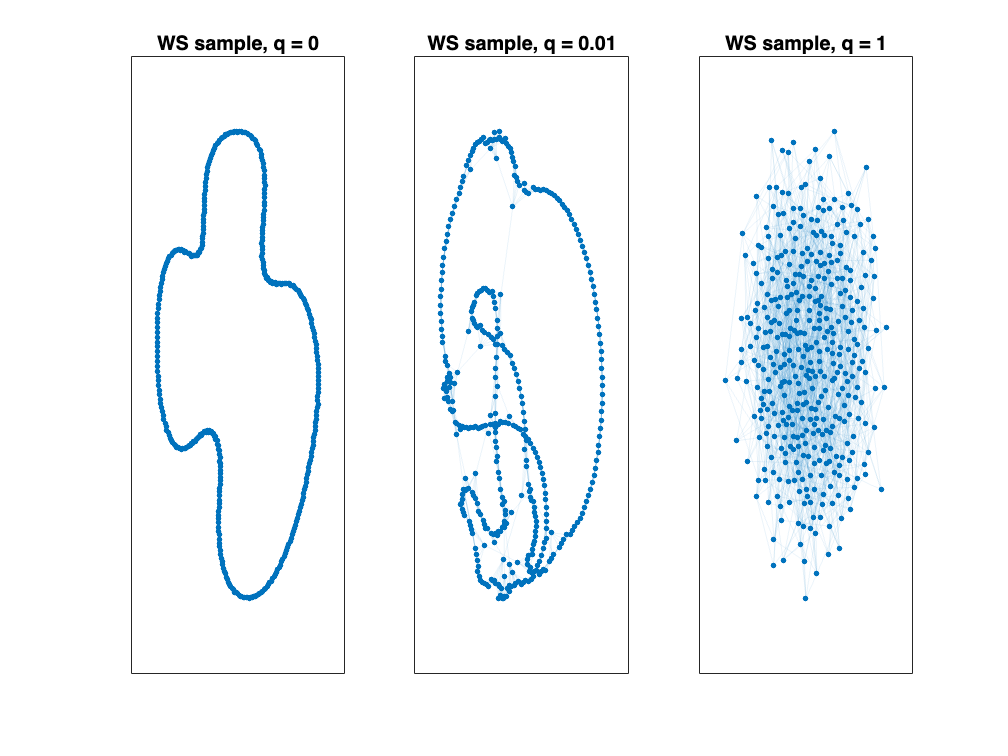

n = 400;
K = 4;              % initial degree = 2K = 8
qVals = [0 0.01 1];

figure('Name', 'WS sample graphs');
tiledlayout(1, 3);
for i = 1:numel(qVals)
    G = make_ws_graph(n, K, qVals(i));
    nexttile;
    plot(G, 'Layout', 'force', 'NodeLabel', {}, 'MarkerSize', 2, 'EdgeAlpha', 0.08);
    title(sprintf('WS sample, q = %.2g', qVals(i)));
end

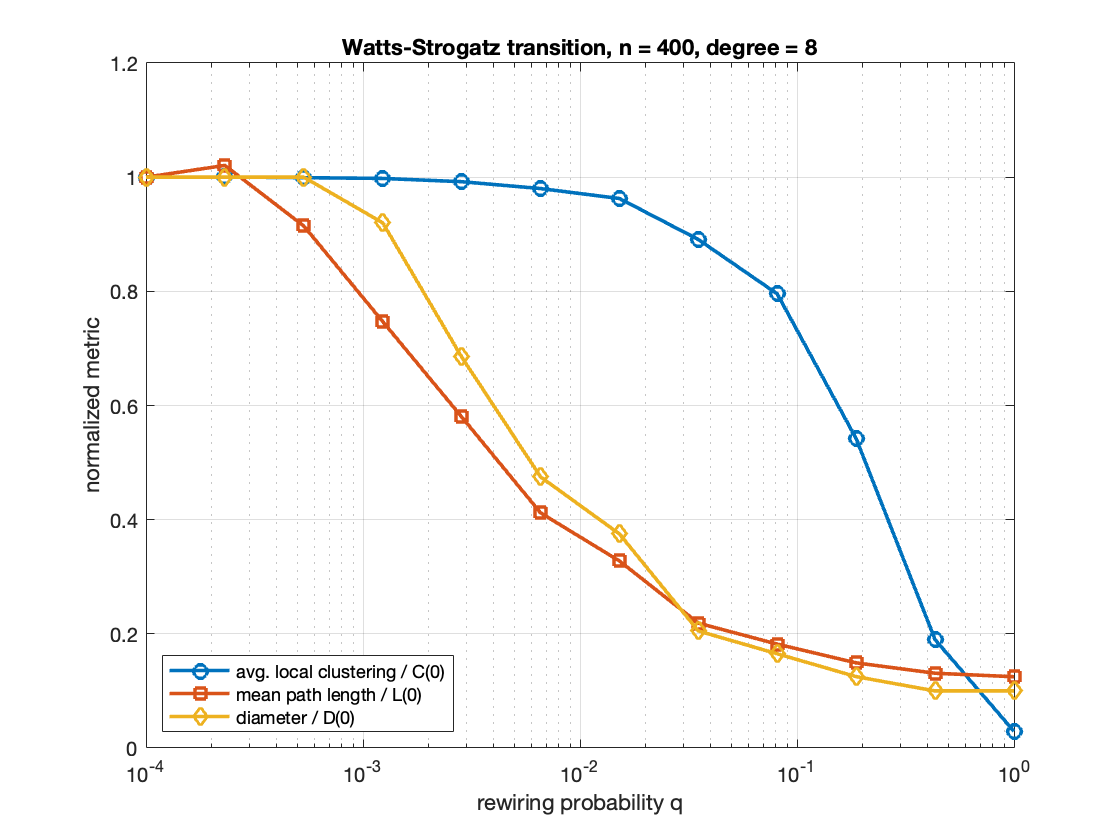


qSweep = logspace(-4, 0, 12);
reps = 4;

clustMean = zeros(numel(qSweep), reps);
pathMean = zeros(numel(qSweep), reps);
diamMean = zeros(numel(qSweep), reps);

for ii = 1:numel(qSweep)
    q = qSweep(ii);

    for r = 1:reps
        G = make_ws_graph(n, K, q);
        c = local_clustering_coefficients(G);
        clustMean(ii, r) = mean(c);

        [L, D] = path_length_stats(G, true);
        pathMean(ii, r) = L;
        diamMean(ii, r) = D;
    end
end

clustAvg = mean(clustMean, 2);
pathAvg = mean(pathMean, 2);
diamAvg = mean(diamMean, 2);

figure('Name', 'WS q sweep metrics');
semilogx(qSweep, clustAvg / clustAvg(1), 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
semilogx(qSweep, pathAvg / pathAvg(1), 's-', 'LineWidth', 1.8, 'MarkerSize', 7);
semilogx(qSweep, diamAvg / diamAvg(1), 'd-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold off;
xlabel('rewiring probability q');
ylabel('normalized metric');
title(sprintf('Watts-Strogatz transition, n = %d, degree = %d', n, 2*K));
legend('avg. local clustering / C(0)', ...
       'mean path length / L(0)', ...
       'diameter / D(0)', ...
       'Location', 'southwest');
grid on;


fprintf('\nWS demo finished.\n');


WS demo finished.


fprintf('As q increases, the path length and diameter drop quickly,\n');

As q increases, the path length and diameter drop quickly,


fprintf('while clustering decays more slowly. This is the small-world window.\n\n');

while clustering decays more slowly. This is the small-world window.

